% AAE 532 HW 7 Problem 1
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps7';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format shortG;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
mars = planet_consts.mars;  % structure of mars
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)
% Set the given constants 
a1 = 6*mars.mer;  % semi major axis [km]
AOP1 = 30;  %  argument of periapsis [deg]
e1 = 0.5;  % eccentricity 
TA1 = 150;  % true anomaly [deg]
RAAN1 = 45;  % right ascension of the ascending node [deg]
i1 = 30;  % inclination [deg]
AOL1 = TA1 + AOP1;  % argument of latitude [deg] 
mu = mars.gp;  % gravitational parameter 

% Other orbital parameters at the maneuver point 
p1 = a1*(1 - e1^2)  % semi latus rectum

p1 =         15287


r1 = p1 / (1 + e1 * cosd(TA1))  % radial distance 

r1 =         26961


v1 = vis_viva(r1, a1, mu)  % velocity 

v1 =        1.0372


FPA1 = acosd(sqrt(mu * p1) / r1 / v1)  % flight path angle

FPA1 =        23.794


rp1 = a1 * (1 - e1);
rp1vec = orbit_frame_transform(0+AOP1, i1, RAAN1, [rp1, 0, 0], "orbital", "deg");

% Transform the delta v from the inertial frame to the orbital frame 
dv_i = [0.1, 0.25, 0.35];  % delta v in the inertial frame 
dvvec = orbit_frame_transform(AOL1, i1, RAAN1, dv_i, "inertial", "deg")

dvvec = struct with fields:
    n: [0.24749 0.10607 0.35]
    q: [0.24749 0.26686 0.25008]
    o: [-0.24749 -0.26686 0.25008]


dvvec.i = dv_i;
temp = abs(dvvec.o(3))/norm(dvvec.o) * 100

temp =        56.631



dv_rtheta = dvvec.o(1:2)

dv_rtheta =      -0.24749     -0.26686


v1vec.o = v1 * [sind(FPA1), cosd(FPA1), 0]

v1vec = struct with fields:
    o: [0.41846 0.94904 0]


dv = norm(dvvec.o);
alpha = acos_dbval(dot(v1vec.o(1:2), dv_rtheta) / v1 / norm(dv_rtheta), "deg")

alpha =        160.95      -160.95



beta = asin_dbval(dvvec.o(3)/dv, "deg")

beta =        34.493       145.51


beta = beta(1)

beta =        34.493



% determine phi
phi1 = acos_dbval(dvvec.o(2)/dv/cosd(beta), "deg")

phi1 =        137.16      -137.16


phi2 = asin_dbval(dvvec.o(1)/dv/cosd(beta), "deg")

phi2 =       -42.843      -137.16


phi = intersect(round(phi1, 2), round(phi2, 2))

phi =       -137.16



alpha = alpha(alpha < 0)

alpha =       -160.95


dvvec.vnb = dv * [cosd(beta)*cosd(alpha), cosd(beta)*sind(alpha), sind(beta)]

dvvec = struct with fields:
      n: [0.24749 0.10607 0.35]
      q: [0.24749 0.26686 0.25008]
      o: [-0.24749 -0.26686 0.25008]
      i: [0.1 0.25 0.35]
    vnb: [-0.34402 -0.11879 0.25008]


% (b)

% Transforming the position vectors into inertial frames and getting the
% vectors after the maneuver 
r1vec.o = r1 * [1, 0, 0];
r1vec = catstruct(orbit_frame_transform(AOL1, i1, RAAN1, r1vec.o, "orbital", "deg"), r1vec)

r1vec = struct with fields:
    q: [-26961 0 0]
    n: [-26961 0 0]
    i: [-19064 -19064 0]
    o: [26961 0 0]


v1vec = catstruct(orbit_frame_transform(AOL1, i1, RAAN1, v1vec.o, "orbital", "deg"), v1vec)

v1vec = struct with fields:
    q: [-0.41846 -0.94904 0]
    n: [-0.41846 -0.82189 -0.47452]
    i: [0.28527 -0.87706 -0.47452]
    o: [0.41846 0.94904 0]



h1vec = cross(r1vec.i, v1vec.i)

h1vec =        9046.4      -9046.4        22159


v2vec.i = v1vec.i + dvvec.i

v2vec = struct with fields:
    i: [0.38527 -0.62706 -0.12452]


% (c)
r2vec = r1vec;
r2 = norm(r1vec.i)

r2 =         26961


v2 = norm(v2vec.i)

v2 =       0.74642


r2hat = r2vec.i / r2

r2hat =      -0.70711     -0.70711            0


a2 = -mu / (v2^2/2 - mu/r2) / 2

a2 =         16347


h2vec = cross(r2vec.i, v2vec.i)

h2vec =        2373.9      -2373.9        19299


h2 = norm(h2vec)

h2 =         19589


e2 = sqrt(1 - h2^2 / mu / a2)

e2 =       0.67224


h2hat = h2vec / h2

h2hat =       0.12118     -0.12118      0.98521


theta2hat = cross(h2hat, r2hat)

theta2hat =       0.69665     -0.69665     -0.17138


i2 = acosd(h2hat(3))

i2 =         9.868


RAAN21 = asin_dbval(h2hat(1)/sind(i2), "deg")

RAAN21 =            45          135


RAAN22 = acos_dbval(-h2hat(2)/sind(i2), "deg")

RAAN22 =            45          -45


RAAN2 = intersect(round(RAAN21,5), round(RAAN22,5))

RAAN2 =     45


AOL21 = asin_dbval(r2hat(3)/sind(i2), "deg")

AOL21 =      0   180


AOL22 = acos_dbval(theta2hat(3)/sind(i2), "deg")
AOL2 = intersect(round(AOL21,5),round(AOL22,5))

AOL2 =    180


r2dot = dot(v2vec.i, r2hat)

r2dot =       0.17097


p2 = h2^2/mu;
TA2 = acos_dbval(1/e2 * (p2/r2 - 1), "deg")

TA2 =        173.32      -173.32


TA2 = TA2(TA2 > 0)

TA2 =        173.32


AOP2 = AOL2 - TA2

AOP2 =        6.6802



rp2 = a2 * (1 - e2);
rp2vec = orbit_frame_transform(0+AOP2, i2, RAAN2, [rp2, 0, 0], "orbital", "deg");

% (d)
% Plotting 

% old orbit
TAs = 0:0.01:360;
AOLs = TAs + AOP1;
temp = p1 ./ (1 + e1*cosd(TAs)); 
temp = [temp.', zeros([numel(temp), 2])];
R_old.o = temp;
R_old = catstruct(orbit_frame_transform(AOLs, i1, RAAN1, R_old.o, "orbital", "deg"), R_old);
% find AN and DN
temp = find_AN_DN(R_old.i);
nodes_old = [temp.AN.values; temp.DN.values]; 
% New orbit
AOLs = TAs + AOP2;
temp = p2 ./ (1 + e2*cosd(TAs)); 
temp = [temp.', zeros([numel(temp), 2])];
R_new.o = temp;
R_new = catstruct(orbit_frame_transform(AOLs, i2, RAAN2, R_new.o, "orbital", "deg"), R_new);
% find AN and DN
temp = find_AN_DN(R_new.i);
nodes_new = [temp.AN.values; temp.DN.values];

fig1 = figure("Renderer","painters","Position",[10, 10, 900, 700]); ax = gca;
plot3(R_old.i(:,1),R_old.i(:,2),R_old.i(:,3))
hold on; grid on; grid minor; box on; axis equal; 
plot3(R_new.i(:,1),R_new.i(:,2),R_new.i(:,3))

% Mars equator
xmin = min([min(R_old.i(:,1)), min(R_new.i(:,1))])

xmin =        -20645


xmax = max([max(R_old.i(:,1)), max(R_new.i(:,1))])

xmax =         13683


ymin = min([min(R_old.i(:,2)), min(R_new.i(:,2))])

ymin =        -28341


ymax = max([max(R_old.i(:,2)), max(R_new.i(:,2))])

ymax =        9619.3


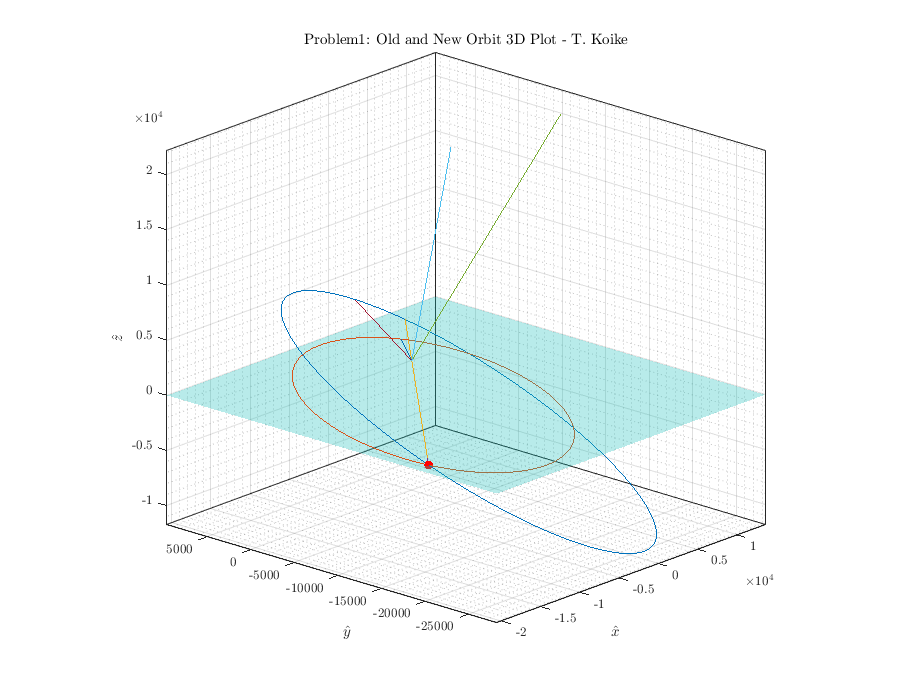

[x_eq, y_eq] = meshgrid(xmin:100:xmax,ymin:100:ymax); % Generate x and y data
z_eq = zeros(size(x_eq)); % Generate z data
s_eq = surf(x_eq, y_eq, z_eq, "FaceAlpha",0.3); % Plot the surface
s_eq.EdgeColor = 'none';

% AN and DN
plot3(nodes_old(:,1), nodes_old(:,2), nodes_old(:,3), '-')
plot3(nodes_new(:,1), nodes_new(:,2), nodes_new(:,3), '-')

% Angular Momentum vector 
plot3([0;h1vec(1)],[0;h1vec(2)],[0;h1vec(3)], '-')
plot3([0;h2vec(1)],[0;h2vec(2)],[0;h2vec(3)], '-')

% Periapsis Vectors
plot3([0;rp1vec.i(1)],[0;rp1vec.i(2)],[0;rp1vec.i(3)], '-')
plot3([0;rp2vec.i(1)],[0;rp2vec.i(2)],[0;rp2vec.i(3)], '-')

% Maneuver location
plot3(r1vec.i(1), r1vec.i(2), r1vec.i(3), '.r', "MarkerSize", 22)

hold off 
title("Problem1: Old and New Orbit 3D Plot - T. Koike")
xlabel("$\hat{x}$")
ylabel("$\hat{y}$")
zlabel("$\hat{z}$")
saveas(fig1, fullfile(fdir, "p1_view1.png"));

fig2 = figure("Renderer","painters","Position",[10, 10, 900, 700]); ax = gca;
plot3(R_old.i(:,1),R_old.i(:,2),R_old.i(:,3))
hold on; grid on; grid minor; box on; axis equal; 
plot3(R_new.i(:,1),R_new.i(:,2),R_new.i(:,3))

% Mars equator
xmin = min([min(R_old.i(:,1)), min(R_new.i(:,1))])

xmin =        -20645


xmax = max([max(R_old.i(:,1)), max(R_new.i(:,1))])

xmax =         13683


ymin = min([min(R_old.i(:,2)), min(R_new.i(:,2))])

ymin =        -28341


ymax = max([max(R_old.i(:,2)), max(R_new.i(:,2))])

ymax =        9619.3


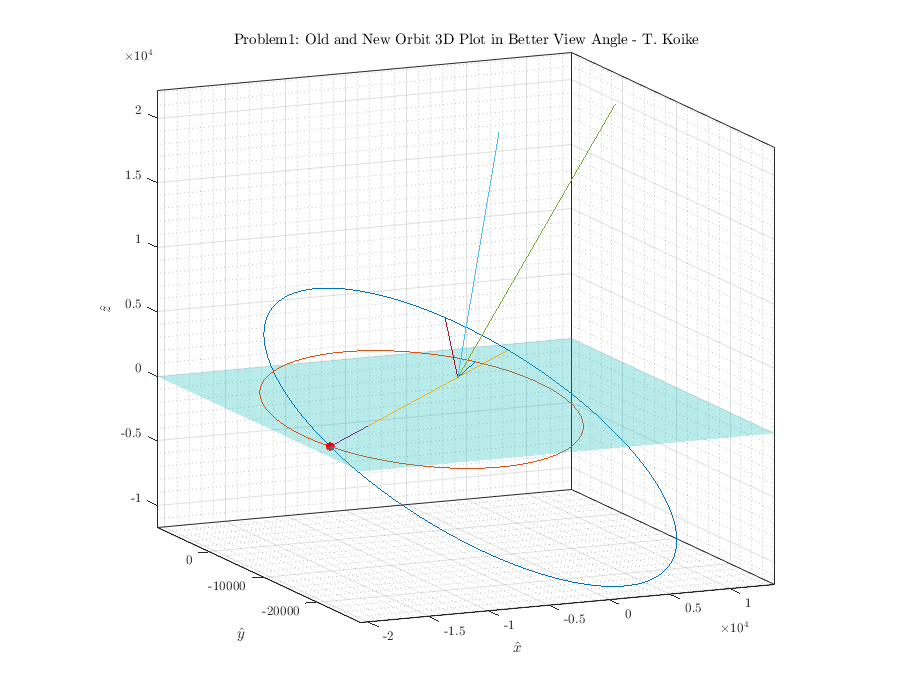

[x_eq, y_eq] = meshgrid(xmin:100:xmax,ymin:100:ymax); % Generate x and y data
z_eq = zeros(size(x_eq)); % Generate z data
s_eq = surf(x_eq, y_eq, z_eq, "FaceAlpha",0.3); % Plot the surface
s_eq.EdgeColor = 'none';

% AN and DN
plot3(nodes_old(:,1), nodes_old(:,2), nodes_old(:,3), '-')
plot3(nodes_new(:,1), nodes_new(:,2), nodes_new(:,3), '-')

% Angular Momentum vector 
plot3([0;h1vec(1)],[0;h1vec(2)],[0;h1vec(3)], '-')
plot3([0;h2vec(1)],[0;h2vec(2)],[0;h2vec(3)], '-')

% Periapsis Vectors
plot3([0;rp1vec.i(1)],[0;rp1vec.i(2)],[0;rp1vec.i(3)], '-')
plot3([0;rp2vec.i(1)],[0;rp2vec.i(2)],[0;rp2vec.i(3)], '-')

% Maneuver location
plot3(r1vec.i(1), r1vec.i(2), r1vec.i(3), '.r', "MarkerSize", 22)

hold off 
title("Problem1: Old and New Orbit 3D Plot in Better View Angle - T. Koike")
xlabel("$\hat{x}$")
ylabel("$\hat{y}$")
zlabel("$\hat{z}$")
view([-24 12])
saveas(fig2, fullfile(fdir, "p1_view2.png"));

fig3 = figure("Renderer","painters","Position",[10, 10, 900, 700]); ax = gca;
plot3(R_old.i(:,1),R_old.i(:,2),R_old.i(:,3))
hold on; grid on; grid minor; box on; axis equal; 
plot3(R_new.i(:,1),R_new.i(:,2),R_new.i(:,3))

% Mars equator
xmin = min([min(R_old.i(:,1)), min(R_new.i(:,1))])

xmin =        -20645


xmax = max([max(R_old.i(:,1)), max(R_new.i(:,1))])

xmax =         13683


ymin = min([min(R_old.i(:,2)), min(R_new.i(:,2))])

ymin =        -28341


ymax = max([max(R_old.i(:,2)), max(R_new.i(:,2))])

ymax =        9619.3


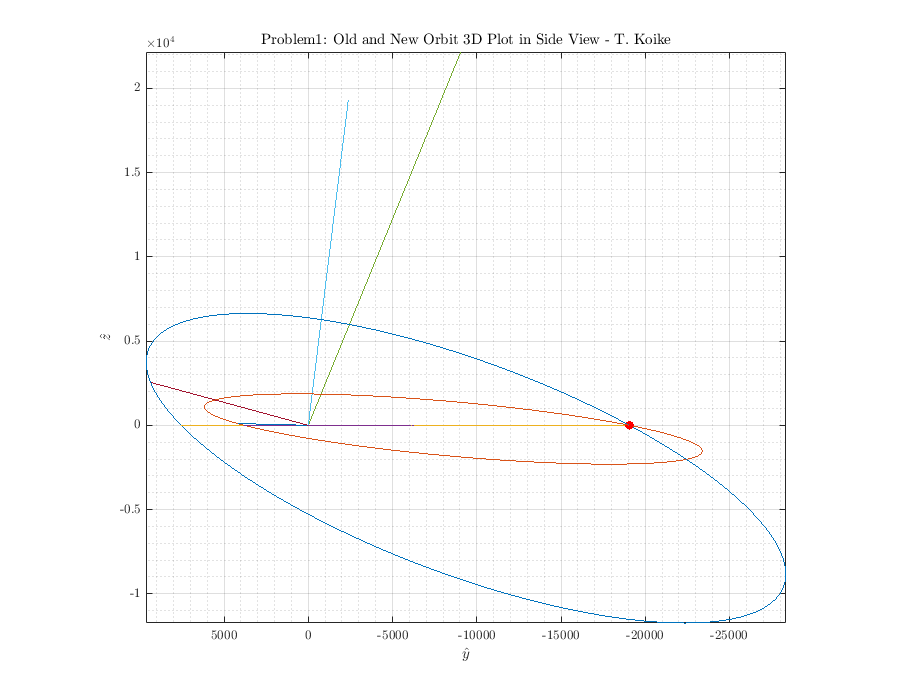

[x_eq, y_eq] = meshgrid(xmin:100:xmax,ymin:100:ymax); % Generate x and y data
z_eq = zeros(size(x_eq)); % Generate z data
s_eq = surf(x_eq, y_eq, z_eq, "FaceAlpha",0.3); % Plot the surface
s_eq.EdgeColor = 'none';

% AN and DN
plot3(nodes_old(:,1), nodes_old(:,2), nodes_old(:,3), '-')
plot3(nodes_new(:,1), nodes_new(:,2), nodes_new(:,3), '-')

% Angular Momentum vector 
plot3([0;h1vec(1)],[0;h1vec(2)],[0;h1vec(3)], '-')
plot3([0;h2vec(1)],[0;h2vec(2)],[0;h2vec(3)], '-')

% Periapsis Vectors
plot3([0;rp1vec.i(1)],[0;rp1vec.i(2)],[0;rp1vec.i(3)], '-')
plot3([0;rp2vec.i(1)],[0;rp2vec.i(2)],[0;rp2vec.i(3)], '-')

% Maneuver location
plot3(r1vec.i(1), r1vec.i(2), r1vec.i(3), '.r', "MarkerSize", 22)

hold off 
title("Problem1: Old and New Orbit 3D Plot in Side View - T. Koike")
xlabel("$\hat{x}$")
ylabel("$\hat{y}$")
zlabel("$\hat{z}$")
view([-90 0])

saveas(fig3, fullfile(fdir, "p1_view3.png"));